% Add DebugData as an output
function [X_Est, P_Est, GT, DebugData] = myEKF(out)
% myEKF Estimates robot 2D pose (x, y, yaw) using an Extended Kalman Filter.
% VERSION: Integrates forward accelerometer for velocity estimation. Mag updates DISABLED. Adds Debug Output.

    % --- User Configuration ---
    gyro_yaw_rate_axis = 1;
    accel_forward_axis = 2; % User confirmed this works better
    gyro_bias_z = 0.0015;
    accel_bias_fwd = 0.006;  % User provided this value
    % --- End User Configuration ---

    % --- Tuning Parameters ---
    process_noise_pos = 0.5;
    process_noise_yaw_rate = (1 * pi/180);
    process_noise_accel = 0.5;
    % --- End Tuning Parameters ---

    % --- Extract Data ---
    GT_position_val = squeeze(out.GT_position.signals.values);
    GT_rotation_val = squeeze(out.GT_rotation.signals.values);
    GT_time_vec     = ensureColumnVec(squeeze(out.GT_time.time));
    Sensor_GYRO_val   = squeeze(out.Sensor_GYRO.signals.values);
    Sensor_GYRO_time  = ensureColumnVec(squeeze(out.Sensor_GYRO.time));
    Sensor_ACCEL_val = squeeze(out.Sensor_ACCEL.signals.values);
    Sensor_ACCEL_time= ensureColumnVec(squeeze(out.Sensor_ACCEL.time));

    % --- Validate Dimensions ---
    [Sensor_GYRO_val, Sensor_GYRO_time] = validateAndOrient(Sensor_GYRO_val, Sensor_GYRO_time, 3, 'Gyro');
    [Sensor_ACCEL_val, Sensor_ACCEL_time] = validateAndOrient(Sensor_ACCEL_val, Sensor_ACCEL_time, 3, 'Accel');

    % --- Initialize ---
    N = length(GT_time_vec);
    if N == 0; error('myEKF: Ground truth time vector is empty.'); end
    if isempty(Sensor_GYRO_val); error('myEKF: Gyro data is empty or invalid.'); end
    if isempty(Sensor_ACCEL_val); error('myEKF: Accelerometer data is empty or invalid.'); end

    n = 3; % State dimension [x, y, yaw]
    eul = quat2eul(GT_rotation_val, 'ZYX');
    yaw_ground_truth = eul(:, 1);
    GT = [GT_position_val(:, 1), GT_position_val(:, 2), wrapToPi(yaw_ground_truth)];

    X_Est = zeros(N, n);
    P_Est = zeros(n, n, N);
    X_Est(1, :) = GT(1, :);
    P_Est(:, :, 1) = diag([0.01^2, 0.01^2, (0.1*pi/180)^2]);

    last_valid_gyro_idx = find(~isnan(Sensor_GYRO_val(:,gyro_yaw_rate_axis)), 1, 'first');
    last_valid_accel_idx = find(~isnan(Sensor_ACCEL_val(:,accel_forward_axis)), 1, 'first');

    % Initialize velocity and Debug Output
    current_v_est = 0.1; % User changed this
    DebugData = struct();
    DebugData.Time = GT_time_vec;
    DebugData.VelocityEstimate = NaN(N, 1);
    DebugData.CorrectedAccel = NaN(N, 1); % Also store corrected accel
    DebugData.VelocityEstimate(1) = current_v_est;

    % --- Main Loop ---
    for k = 2:N
        dt = GT_time_vec(k) - GT_time_vec(k-1);
        if dt <= 0
            X_Est(k, :) = X_Est(k-1, :);
            P_Est(:, :, k) = P_Est(:, :, k-1);
            if k > 1 % Store previous debug data if skipping step
                DebugData.VelocityEstimate(k) = DebugData.VelocityEstimate(k-1);
                DebugData.CorrectedAccel(k) = DebugData.CorrectedAccel(k-1);
            end
            continue;
        end

        % --- Update Velocity Estimate ---
        idx_accel = find(Sensor_ACCEL_time <= GT_time_vec(k-1), 1, 'last');
        accel_fwd_raw = 0;
        if ~isempty(idx_accel) && idx_accel <= size(Sensor_ACCEL_val, 1) && ~isnan(Sensor_ACCEL_val(idx_accel, accel_forward_axis))
            accel_fwd_raw = Sensor_ACCEL_val(idx_accel, accel_forward_axis);
            last_valid_accel_idx = idx_accel;
        elseif ~isempty(last_valid_accel_idx) && last_valid_accel_idx <= size(Sensor_ACCEL_val, 1) && ~isnan(Sensor_ACCEL_val(last_valid_accel_idx, accel_forward_axis))
            accel_fwd_raw = Sensor_ACCEL_val(last_valid_accel_idx, accel_forward_axis);
        end
        accel_fwd_corrected = accel_fwd_raw - accel_bias_fwd;
        current_v_est = current_v_est + accel_fwd_corrected * dt;

        % Store debug data
        DebugData.VelocityEstimate(k) = current_v_est;
        DebugData.CorrectedAccel(k) = accel_fwd_corrected; % Store corrected accel


        % --- Prediction Step ---
        x_prev = X_Est(k-1, :)';
        P_prev = P_Est(:, :, k-1);
        yaw_prev = x_prev(3);

        idx_gyro = find(Sensor_GYRO_time <= GT_time_vec(k-1), 1, 'last');
        omega_z_raw = 0;
        if ~isempty(idx_gyro) && idx_gyro <= size(Sensor_GYRO_val, 1) && ~isnan(Sensor_GYRO_val(idx_gyro, gyro_yaw_rate_axis))
            omega_z_raw = Sensor_GYRO_val(idx_gyro, gyro_yaw_rate_axis);
            last_valid_gyro_idx = idx_gyro;
        elseif ~isempty(last_valid_gyro_idx) && last_valid_gyro_idx <= size(Sensor_GYRO_val, 1) && ~isnan(Sensor_GYRO_val(last_valid_gyro_idx, gyro_yaw_rate_axis))
            omega_z_raw = Sensor_GYRO_val(last_valid_gyro_idx, gyro_yaw_rate_axis);
        end
        omega_z_corrected = omega_z_raw - gyro_bias_z;

        x_pred = [ x_prev(1) + current_v_est * cos(yaw_prev) * dt;
                   x_prev(2) + current_v_est * sin(yaw_prev) * dt;
                   yaw_prev + omega_z_corrected * dt ];
        x_pred(3) = wrapToPi(x_pred(3));

        F_k = [ 1  0  -current_v_est * sin(yaw_prev) * dt;
                0  1   current_v_est * cos(yaw_prev) * dt;
                0  0   1 ];

        Q_pos_from_accel = (0.5 * process_noise_accel * dt^2)^2;
        Q_k = diag([ (process_noise_pos * dt)^2 + Q_pos_from_accel, ...
                     (process_noise_pos * dt)^2 + Q_pos_from_accel, ...
                     (process_noise_yaw_rate * dt)^2 ]);

        P_pred = F_k * P_prev * F_k' + Q_k;
        P_pred = (P_pred + P_pred')/2;

        % --- Measurement Update Step (DISABLED) ---
        perform_update = false;

        % --- EKF Update ---
        if perform_update % Always false
             % ...
        else % No measurement update
            X_Est(k, :) = x_pred';
            P_Est(:, :, k) = P_pred;
        end
    end % End main loop
end % End function

% --- Helper Functions ---
function [dataOut, timeOut] = validateAndOrient(dataIn, timeIn, expectedCols, name)
    dataOut = []; timeOut = ensureColumnVec(timeIn);
    if isempty(dataIn); return; end; if isempty(timeOut); dataOut = []; return; end
    if size(dataIn, 2) ~= expectedCols && size(dataIn, 1) == expectedCols; warning('validateAndOrient: %s data seems transposed (%dxN). Transposing to Nx%d.', name, expectedCols, expectedCols); dataTemp = dataIn';
    elseif size(dataIn, 2) == expectedCols; dataTemp = dataIn;
    else; warning('validateAndOrient: %s data does not have %d columns. Found %d. Returning empty.', name, expectedCols, size(dataIn,2)); return; end
    if size(dataTemp, 1) ~= numel(timeOut); warning('validateAndOrient: %s data (%d rows) and time vector (%d elements) length mismatch. Returning empty.', name, size(dataTemp,1), numel(timeOut)); return; end
    dataOut = dataTemp;
end
function timeVecOut = ensureColumnVec(timeVecIn); if isrow(timeVecIn); timeVecOut = timeVecIn'; else; timeVecOut = timeVecIn; end; end
function angle = wrapToPi(angle); angle = mod(angle + pi, 2*pi) - pi; end

Run

data = load('trainingData/task2_5.mat');
out = data.out;

[X_Est, P_Est, GT] = myEKF(out);

Eval

% Load data (assuming 'out' is already loaded from the .mat file)
% data = load('trainingData/task1_5.mat');
% out = data.out;

% Run EKF (assuming myEKF function is available)
% [X_Est, P_Est, GT_from_EKF] = myEKF(out); % GT_from_EKF is Nx3 [x,y,yaw]

fprintf('Starting Evaluation Script...\n');

Starting Evaluation Script...



% ------------------ Extract Data ------------------ %
pos_GT_orig   = out.GT_position.signals.values;
rot_GT_quat_wxyz = out.GT_rotation.signals.values; % w,x,y,z format
timeVec  = out.GT_time.time;

if isrow(timeVec), timeVec = timeVec'; end
fprintf('Extracted GT Position, Rotation, and Time.\n');

Extracted GT Position, Rotation, and Time.



% --- Handle Potential Transpose Issues ---
if size(pos_GT_orig, 2) ~= 3 && size(pos_GT_orig, 1) == 3, pos_GT_orig = pos_GT_orig'; fprintf('Transposed original GT position data.\n'); end
if size(rot_GT_quat_wxyz, 2) ~= 4 && size(rot_GT_quat_wxyz, 1) == 4, rot_GT_quat_wxyz = rot_GT_quat_wxyz'; fprintf('Transposed original GT rotation data.\n'); end
% --- End Transpose Handling ---

% ------------------ Ensure Consistent Lengths ------------------ %
N_gt_pos = size(pos_GT_orig, 1); N_gt_rot = size(rot_GT_quat_wxyz, 1);
N_time = length(timeVec); N_est = size(X_Est, 1);
N = min([N_gt_pos, N_gt_rot, N_time, N_est]);

if N < max([N_gt_pos, N_gt_rot, N_time, N_est])
    fprintf('--- Warning: Truncating data lengths from max(%d, %d, %d, %d) to shortest N = %d ---\n', N_gt_pos, N_gt_rot, N_time, N_est, N);
    pos_GT = pos_GT_orig(1:N, :); rot_GT_quat_wxyz = rot_GT_quat_wxyz(1:N, :);
    timeVec = timeVec(1:N); X_Est = X_Est(1:N, :);
else
    fprintf('--- Data lengths consistent: N = %d ---\n', N);
    pos_GT = pos_GT_orig;
end

--- Data lengths consistent: N = 4608 ---


if N == 0, error('Effective data length is zero after checking consistency.'); end

% ------------------ Convert Ground Truth Rotation to Yaw ------------------ %
fprintf('Converting Ground Truth rotation to Yaw (N=%d)...\n', N);

Converting Ground Truth rotation to Yaw (N=4608)...


yaw_GT = zeros(N, 1); valid_gt_quat = true(N, 1);
for i = 1:N
    try
        qGT = quaternion(rot_GT_quat_wxyz(i,1), rot_GT_quat_wxyz(i,2), rot_GT_quat_wxyz(i,3), rot_GT_quat_wxyz(i,4));
        qGT = normalize(qGT); eulGT = eulerd(qGT, 'ZYX', 'frame'); yaw_GT(i) = deg2rad(eulGT(1));
    catch ME_gt_conv, warning('Error converting GT quaternion at index %d: %s.', i, ME_gt_conv.message); yaw_GT(i) = NaN; valid_gt_quat(i) = false; end
end
yaw_GT = wrapToPi(yaw_GT);
fprintf('Ground Truth Yaw conversion complete.\n');

Ground Truth Yaw conversion complete.



% ------------------ Get Estimated Yaw ------------------ %
if size(X_Est, 2) < 3, error('X_Est does not contain Yaw data.'); end
yaw_Est = wrapToPi(X_Est(:, 3));
fprintf('Extracted Estimated Yaw.\n');

Extracted Estimated Yaw.



% ------------------ Convert Poses to rigidtform3d (Optional) --- %
fprintf('Converting poses to rigidtform3d arrays (N=%d)...\n', N);

Converting poses to rigidtform3d arrays (N=4608)...


gtTforms(N) = rigidtform3d; estTforms(N) = rigidtform3d;
for i = 1:N
     if valid_gt_quat(i) && ~any(isnan(pos_GT(i,:)))
        qGT = quaternion(rot_GT_quat_wxyz(i,1:4)); qGT = normalize(qGT); RGT = rotmat(qGT, 'frame'); tGT = pos_GT(i,1:min(3,end));
        if length(tGT) == 2, tGT = [tGT, 0]; end; gtTforms(i) = rigidtform3d(RGT, tGT(:)');
     else, gtTforms(i) = rigidtform3d(); end
    if ~any(isnan(X_Est(i, 1:2))) && ~isnan(yaw_Est(i))
        tEst = [X_Est(i, 1), X_Est(i, 2), 0]; yaw_est_i = yaw_Est(i);
        REst = [cos(yaw_est_i), -sin(yaw_est_i), 0; sin(yaw_est_i), cos(yaw_est_i), 0; 0, 0, 1];
        estTforms(i) = rigidtform3d(REst, tEst);
    else, estTforms(i) = rigidtform3d(); end
end
fprintf('Pose conversions complete.\n');

Pose conversions complete.




% ------------------ Compare Trajectories & Calculate Key RMSEs --- % % MODIFIED SECTION
fprintf('\n--- Trajectory Comparison Results ---\n');


--- Trajectory Comparison Results ---



% --- Run compareTrajectories if possible (Optional) ---
metrics = []; canCompare = false;
try % Version/Toolbox check
    v = ver('MATLAB'); versionYear = str2double(regexp(v.Release, 'R(\d{4})[ab]', 'tokens', 'once'));
    if ~isempty(versionYear) && (versionYear >= 2024)
        reqToolbox = 'Navigation Toolbox'; allInstalledToolboxes = ver;
        if any(strcmp({allInstalledToolboxes.Name}, reqToolbox)), canCompare = true; fprintf('MATLAB version/toolbox OK for compareTrajectories.\n');
        else, fprintf('Required toolbox (%s) not found for compareTrajectories.\n', reqToolbox); end
    else, fprintf('MATLAB version might be too old for compareTrajectories.\n'); end
catch ME_ver, warning('Could not determine MATLAB version reliably: %s', ME_ver.message); end

MATLAB version/toolbox OK for compareTrajectories.



if ~canCompare, warning('compareTrajectories requires specific MATLAB version/toolbox. Skipping.');
else % Attempt to run compareTrajectories
    try
        validIdx = arrayfun(@(x) ~isequal(x.Rotation, eye(3)), estTforms) & arrayfun(@(x) ~isequal(x.Rotation, eye(3)), gtTforms);
        if sum(validIdx) < 2, warning('Not enough valid transforms (%d) to run compareTrajectories.', sum(validIdx));
        else
            metrics = compareTrajectories(estTforms(validIdx), gtTforms(validIdx), 'AlignmentType', 'rigid');
            fprintf('compareTrajectories executed (Specific metrics below are calculated manually).\n');
            % Optional plotting from metrics object can remain if desired
            % try, figure('Name', 'compareTrajectories Plot'); plot(metrics, "absolute-translation"); title('Absolute Translation Error (compareTrajectories)'); grid on; catch plotME, warning('Failed to plot metrics: %s', plotME.message); end
        end
    catch ME_compare, warning('Failed to execute compareTrajectories: %s', ME_compare.message); end
end

compareTrajectories executed (Specific metrics below are calculated manually).


% --- End Optional compareTrajectories ---

% --- Calculate and Print Manual Position and Yaw Absolute RMSE --- % ADDED BACK
% Position RMSE (Manual Calculation)
valid_pos_idx = ~isnan(X_Est(:, 1)) & ~isnan(X_Est(:, 2)) & ~isnan(pos_GT(:, 1)) & ~isnan(pos_GT(:, 2));
if sum(valid_pos_idx) > 0 && size(X_Est, 2) >= 2 && size(pos_GT, 2) >= 2
    pos_err_x = X_Est(valid_pos_idx, 1) - pos_GT(valid_pos_idx, 1);
    pos_err_y = X_Est(valid_pos_idx, 2) - pos_GT(valid_pos_idx, 2);
    squared_pos_err = pos_err_x.^2 + pos_err_y.^2;
    rmse_position = sqrt(mean(squared_pos_err));
    fprintf('Position Absolute RMSE (Manual) (m):     %.4f\n', rmse_position); % Output this
else
    fprintf('Position Absolute RMSE (Manual) (m):     Cannot calculate.\n');
    rmse_position = NaN;
end

Position Absolute RMSE (Manual) (m):     6.1573



% Yaw RMSE (Manual Calculation)
valid_yaw_idx = ~isnan(yaw_Est) & ~isnan(yaw_GT);
if sum(valid_yaw_idx) > 0
    yaw_error = wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx));
    squared_yaw_err = yaw_error.^2;
    rmse_yaw_rad = sqrt(mean(squared_yaw_err));
    rmse_yaw_deg = rad2deg(rmse_yaw_rad);
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    %.4f\n', rmse_yaw_deg); % Output this
else
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    Cannot calculate.\n');
    rmse_yaw_deg = NaN;
end

Yaw Absolute RMSE (Manual) (degrees):    0.3652


% --- End Manual RMSE Calculation & Print ---

fprintf('--- End Trajectory Comparison Results ---\n\n');

--- End Trajectory Comparison Results ---



% --- END MODIFIED SECTION ---


% ------------------ Plot Position Comparison (Subplots) ------------------ %
fprintf('Plotting Position: Ground Truth (Left) vs Estimate (Right)...\n');

Plotting Position: Ground Truth (Left) vs Estimate (Right)...


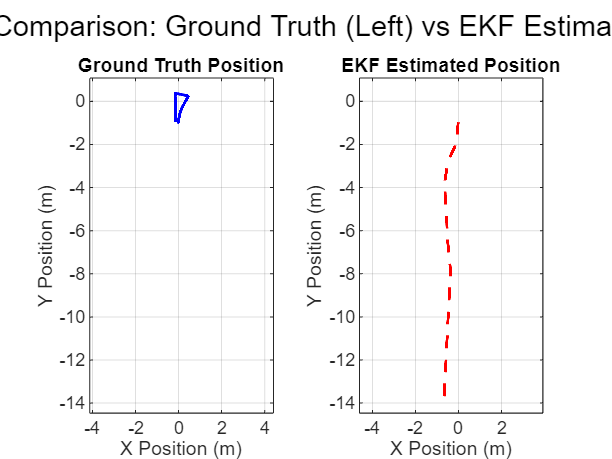

figure('Name', 'Position Comparison');
all_x = [pos_GT(:,1); X_Est(:,1)]; all_y = [pos_GT(:,2); X_Est(:,2)];
x_lim = [min(all_x) max(all_x)]; y_lim = [min(all_y) max(all_y)];
x_range = diff(x_lim); y_range = diff(y_lim); margin = 0.05;
x_lim = x_lim + [-x_range*margin, x_range*margin]; y_lim = y_lim + [-y_range*margin, y_range*margin];
if x_range == 0, x_lim = x_lim + [-0.1, 0.1]; end; if y_range == 0, y_lim = y_lim + [-0.1, 0.1]; end

subplot(1, 2, 1); % GT Position
plot(pos_GT(:,1), pos_GT(:,2), 'b-', 'LineWidth', 1.5);
title('Ground Truth Position'); xlabel('X Position (m)'); ylabel('Y Position (m)');
xlim(x_lim); ylim(y_lim); axis equal; grid on;

subplot(1, 2, 2); % Est Position
plot(X_Est(:,1), X_Est(:,2), 'r--', 'LineWidth', 1.5);
title('EKF Estimated Position'); xlabel('X Position (m)'); ylabel('Y Position (m)');
xlim(x_lim); ylim(y_lim); axis equal; grid on;

try, sgtitle('Position Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end



% ------------------ Plot Yaw Comparison (Subplots) ------------------ %
fprintf('Plotting Yaw: Ground Truth (Left) vs Estimate (Right)...\n');

Plotting Yaw: Ground Truth (Left) vs Estimate (Right)...


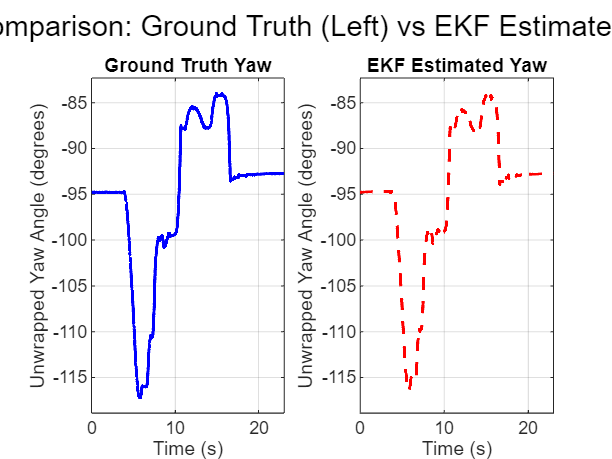

figure('Name', 'Yaw Comparison');
if sum(valid_yaw_idx) > 0
    unwrapped_yaw_gt_deg = rad2deg(unwrap(yaw_GT(valid_yaw_idx))); unwrapped_yaw_est_deg = rad2deg(unwrap(yaw_Est(valid_yaw_idx)));
    all_yaw_deg = [unwrapped_yaw_gt_deg; unwrapped_yaw_est_deg]; y_lim_yaw = [min(all_yaw_deg) max(all_yaw_deg)];
    y_range_yaw = diff(y_lim_yaw); y_lim_yaw = y_lim_yaw + [-y_range_yaw*margin, y_range_yaw*margin];
    if y_range_yaw == 0, y_lim_yaw = y_lim_yaw + [-10, 10]; end

    subplot(1, 2, 1); % GT Yaw
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_gt_deg, 'b-', 'LineWidth', 1.5);
    title('Ground Truth Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;

    subplot(1, 2, 2); % Est Yaw
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_est_deg, 'r--', 'LineWidth', 1.5);
    title('EKF Estimated Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;

    try, sgtitle('Yaw Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end
else, subplot(1,1,1); title('Yaw Comparison (No valid data to plot)'); end



% ------------------ Plot Yaw Error ------------------ %
fprintf('Plotting Yaw Estimation Error...\n');

Plotting Yaw Estimation Error...


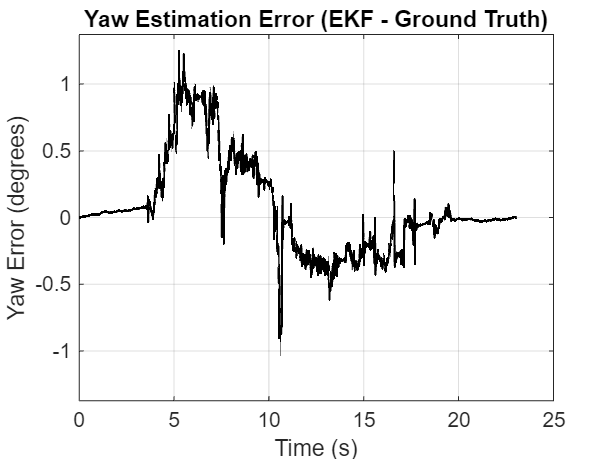

figure('Name', 'Yaw Estimation Error');
if sum(valid_yaw_idx) > 0
    yaw_error_deg = rad2deg(wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx)));
    plot(timeVec(valid_yaw_idx), yaw_error_deg, 'k-', 'LineWidth', 1);
    xlabel('Time (s)'); ylabel('Yaw Error (degrees)'); title('Yaw Estimation Error (EKF - Ground Truth)'); grid on;
    max_err = max(abs(yaw_error_deg));
    if ~isnan(max_err) && max_err > 0, ylim([-max(1, max_err*1.1), max(1, max_err*1.1)]); end
else, title('Yaw Estimation Error (No valid data to plot)'); end


fprintf('--- End of Evaluation Script ---\n');

--- End of Evaluation Script ---
